# risolve - Analisi di accuratezza, robustezza e prestazioni

In questo documento sono mostrate le analisi relative all'algoritmo implementato. 

# Accuratezza

In prima analisi, si osservano i risultati riguardanti l'accuratezza degli algoritmi implementati. In particolare, è stata scritta e allegata alla documentazione la funzione `compute_accuracy` che, a partire da un problema e la relativa soluzione, effettua un'esecuzione dell'algoritmo e calcola l'errore relativo della soluzione. Poiché l'accuratezza della soluzione è strettamente collegata all'indice di condizionamento della matrice dei coefficienti, viene mostrato anch'esso.

Gli algoritmi di `back_substitution `e `forward_substitution `sono utilizzati nel caso di matrici triangolari superiori e inferiori rispettivamente: come ci si aspetta, se la matrice `A `dei coefficienti è ben condizionata, la soluzione è accurata.

A = triu(rand(100)) + 2*diag(ones(100,1)); % matrice diagonale superiore bencondizionata
x = ones(100,1);
b = A*x;
[condizionamento, err] = compute_accuracy(A,x,b,'sup')

condizionamento = 101.0713

err = 5.0564e-15

A = tril(rand(100)) + diag(ones(100,1)); % matrice diagonale inferiore bencondizionata
x = ones(100,1);
b = A*x;
[condizionamento, err] = compute_accuracy(A,x,b,'inf')

condizionamento = 587.0900

err = 8.1384e-15

A = triu(rand(100)); % matrice malcondizionata
x = ones(100,1);
b = A*x;
[condizionamento, err] = compute_accuracy(A,x,b,'sup')

condizionamento = 6.8317e+18

err = 38.2754

*Si osservi che nell'ultimo test, in cui la matrice è molto malcondizionata, neanche una cifra del risultato è corretta!*

Per quanto riguarda le matrici piene, l'algoritmo esegue la funzione locale `lin_solve`: anche in questo caso, l'accuratezza della soluzione dipende dal condizionamento della matrice. Inoltre, la funzione implementata per il test dell'accuratezza verifica la validità del teorema di Wilkinson restituendo anche il `residuo`, ed è immediato osservare che, nel caso di matrici ben condizionate, l'errore relativo è circa uguale ad esso (la differenza dipende dall'indice di condizionamento).

A = rand(100);
x = ones(100,1);
b = A*x;
[condizionamento, err, residuo] = compute_accuracy(A,x,b,'full')

condizionamento = 1.1728e+03

err = 2.9574e-14

residuo = 3.2692e-16

A = hilb(15);
x = ones(15,1);
b = A*x;
[condizionamento, err, residuo] = compute_accuracy(A,x,b,'full')

condizionamento = 2.4960e+17

err = 1.3598

residuo = 1.6079e-16

# Prestazioni

Sono stati valutati i tempi di esecuzione dell'algoritmo implementato rispetto alla soluzione del Matlab (`mldivide, \`) attraverso la funzione `performance_calculator` allegata alla documentazione. Di seguito viene riportata l'esecuzione dei test relativi a matrici piene, la cui complessità computazionale è cubica perché prevede l'esecuzione dell'algoritmo di *fattorizzazione LU, *oltre alle operazioni di `back_substitution `e` forward_substition.`

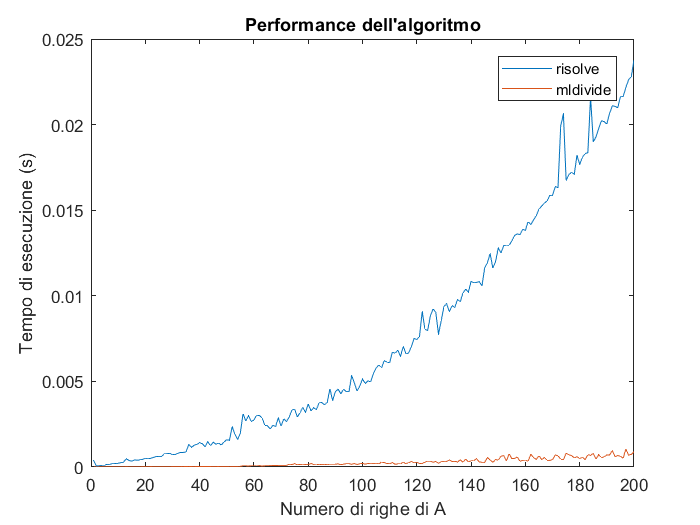

performance_calculator(1,200,1,'full')

Si osservi che la soluzione del Matlab è molto più efficiente perché si avvantaggia di simmetrie presenti nel problema, utilizzando risolutori specifici (si veda la documentazione di `mldivide `per maggiori informazioni).

# Robustezza

Per la progettazione dei casi di test è stato utilizzato il metodo di *Category-partition testing *[1], ampiamente diffuso nell'ambito dell'Ingegneria del Software per il testing funzionale. In particolare, le categorie sono state scelte in base ai parametri modificabili dall'utente; i test effettuati simulano tutte le condizioni di errore/warning che può restituire l'algoritmo.

Per l'implementazione dei casi di test è stato utilizzato il framework di MatLab per il testing di unità [2]*; *questa scelta ha permesso di automatizzare completamente l'esecuzione dei test: infatti, è possibile lanciare la simulazione con l'istruzione:

results = runtests('test_suite.m')

Running test_suite
..........
.....
Done test_suite
__________



results =   1×15 TestResult array with properties:

    Name
    Passed
    Failed
    Incomplete
    Duration
    Details

Totals:
   15 Passed, 0 Failed, 0 Incomplete.
   0.15156 seconds testing time.


Il sistema esegue in automatico i test, riportando in `results `un sommario di quanti hanno avuto successo e dettagliando gli errori in quelli che eventualmente sono falliti.

*N.B. Per semplicità non sono stati implementati i test relativi a dati di input che contenessero valori invalidi *`NaN/Inf`*.*

Di seguito viene descritta l'implementazione di alcuni casi di test a titolo esemplificativo.

## Caso di test 1

La configurazione dei parametri è:

- A: triangolare superiore

- b: valido

- opt: full=true

function testFunctionCase1(testCase)
    A = triu(rand(10));
    x = ones(10,1);
    b = A*x;
    opt.full=true;
    
    testCase.verifyWarning(@()risolve(A,b,opt),'risolve:optError1')
end

La funzione `risolve `esegue l'algoritmo `back_substitution` ma restituisce un warning a causa del fatto che la struttura `opt `passata non ha il campo `sup `settato a `true.`

## Caso di test 5

La configurazione dei parametri è:

- A: triangolare inferiore

- b: valido

- opt: full=true, sup=true

function testFunctionCase5(testCase)
    A = tril(rand(10));
    x = ones(10,1);
    b = A*x;
    opt.full=true;
    opt.sup=true;
    
    testCase.verifyError(@()risolve(A,b,opt),'risolve:optNotCoherent')
end

In questo caso, la struttura `opt `è inconsistente poichè uno e un solo campo di essa può essere `true`.

## Caso di test 8

La configurazione dei parametri è:

- A: triangolare superiore singolare

- b: valido

- opt: sup=true

function testFunctionCase8(testCase)
    A = triu(rand(10));
    A(1,1)=0;
    x = ones(10,1);
    b = A*x;
    opt.sup=true;
    
    testCase.verifyError(@()risolve(A,b,opt),'risolve:ASingular')
end

In questo caso, l'algoritmo verifica che la matrice triangolare passata è singolare e restituisce errore in quanto il sistema non ammette un'unica soluzione. 

## Caso di test 12

La configurazione dei parametri è:

- A: piena, singolare

- b: don''t care

- opt: don't care

function testFunctionCase12(testCase)
    A = rand(10);
    A(2,:)=0;
    x= ones(10,1);
    b = A*x;
    opt.full= true;
    
    testCase.verifyError(@()risolve(A,b,opt),'risolve:ASingular')
end

La condizione di errore restituita è la stessa del caso precedente; tuttavia, mentre nel caso delle matrici triangolari la verifica della singolarità è immediata (una matrice triangolare è singolare se e solo se ha uno zero sulla diagonale), in questo caso la singolarità viene verificata durante la fattorizzazione LU di A.

## Riferimenti                                                                                                                  

[1] *Robert D. Cameron, 2013, *[http://www.cs.sfu.ca/~cameron/Teaching/473/category-partition.html](http://www.cs.sfu.ca/~cameron/Teaching/473/category-partition.html)

[2] Matlab Documentation, [https://it.mathworks.com/help/matlab/function-based-unit-tests.html](https://it.mathworks.com/help/matlab/function-based-unit-tests.html)

## Autori                                                                                                                          

Valerio La Gatta, Marco Postiglione